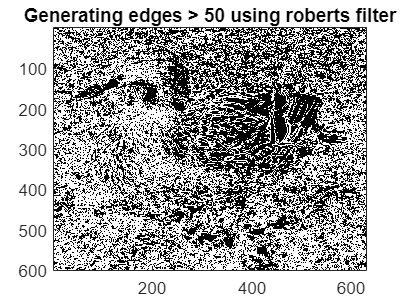

%take in the image 
malard = imread(['D:\Practical\Matlab_ws\Robot Vision [06-25024] Summative_1\Part 1\','Malards.jpg']);

%seperate the red channel 
red_ch = malard(:,:,1);

load roberts.mat

x = conv2(robertsA,red_ch);
y = conv2(robertsB,red_ch);

mag = x.*x + y.*y;
new = sqrt(mag);
show_image(abs(new)>50)
title('Generating edges > 50 using roberts filter')

%first filter
mat1 = [[0,-1,-1,-1,-1,0]
    [-1,-2,-3,-3,-2,-1]
    [-1,-3,12,12,-2,-1]
    [-1,-3,12,12,-3,-1]
    [-1,2,-3,-3,-2,-1]
    [0,-1,-1,-1,-1,0]];
%second filter
mat2 = [[1,1,1,1,1,1]
    [-1,-2,-3,-3,-2,-1]
    [-1,-3,-4,-4,-3,-1]
    [1,3,4,4,3,1]
    [1,2,3,3,2,1]
    [-1,-1,-1,-1,-1,-1]];

mat1,mat2

mat1 =      0    -1    -1    -1    -1     0
    -1    -2    -3    -3    -2    -1
    -1    -3    12    12    -2    -1
    -1    -3    12    12    -3    -1
    -1     2    -3    -3    -2    -1
     0    -1    -1    -1    -1     0


mat2 =      1     1     1     1     1     1
    -1    -2    -3    -3    -2    -1
    -1    -3    -4    -4    -3    -1
     1     3     4     4     3     1
     1     2     3     3     2     1
    -1    -1    -1    -1    -1    -1


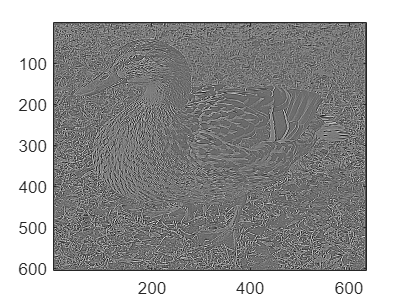


m = rgb2gray(malard);

%convolve using the first filter
c1 = convn(mat1,m);
%convolve using the second filter
c2 = convn(mat2,m);
%display the results
show_image(c1)

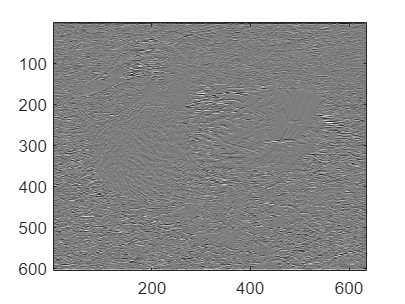

%title('Q 1.2 : First Filter image')
show_image(c2)

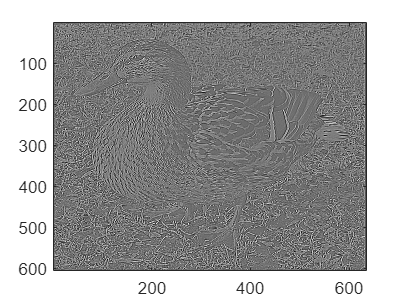

%title('Q 1.2 : Second image')\

%convolve using the first filter
c1T = convn(mat1.',m);
%convolve using the second filter
c2T = convn(mat2.',m);
%display the results
show_image(c1T)

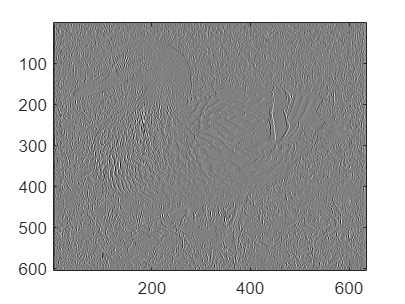

%title('Q 1.2 : First Filter image')
show_image(c2T)

%title('Q 1.2 : Second image')

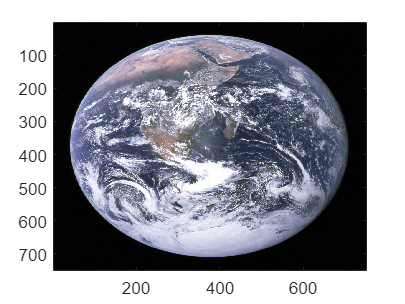

earth = imread(['D:\Practical\Matlab_ws\Robot Vision [06-25024] Summative_1\Part 1\','Earth.jpg']);
fil1 = DiffGaus(im2gray(earth),15,1,2*sqrt(2),1);
fil = DiffGaus(earth,15,1,2*sqrt(2),0);
show_image(earth)

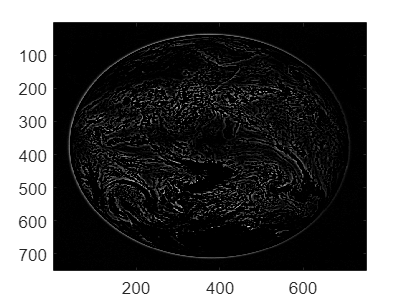

show_image(fil)

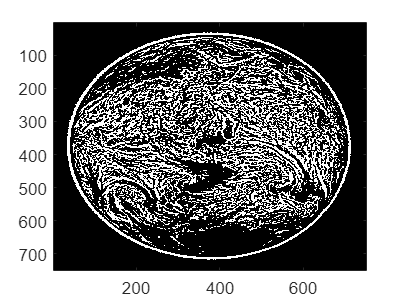

show_image(im2bw(fil,.005))

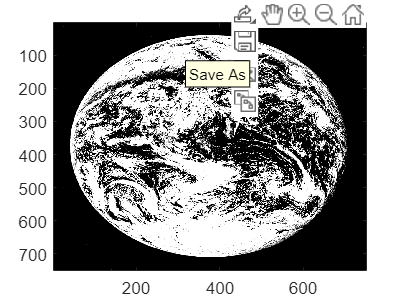

show_image(fil1)

I1 = earth

I1 = 751×750×3 uint8 array
I1(:,:,1) =

     6     1     2     1     5     3     0     5     6     1     0     3     3     2     4     2     1     2     8     0    13     6     0     2     1     2     1     1     0     5     2     1     7     3     2     4     0     2     3     4     1     2     0     2     2     2     4     2     6     5     8     5     2     5     1     3     2     1     1     0     9     1     0     3     2     2     0     4     6     3     0     7     1     4     6     3     0     2     3     2     3     8     0     1     4     8     5     2     3     1     7     4     2     0     2     3     2     1     5     1     0     0     2     3     2     8    13     2     4     4     5     6     2     5     1     0     6     5     2     1     5     0     2     4     4     0     8     1     0     3     2     4     1     3     2     4     3     2     6     0     1     3     0     5     1     0     3     2     6     2     0     1     1     2     1     5     2     5     0     7

im = uint8.empty(0,5);
k=1

k = 1

T1 = 751×750 uint8 matrix
   3   1   3   1   2   2   2   2   2   1   1   2   2   3   3   2   1   2   4   1   7   5   0   2   1   2   1   2   0   4   3   1   4   2   2   3   1   1   3   3   1   1   1   2   2   2   3   2   3   2
   5   2   2   3   1   2   1   3   3   4   2   2   0   2   1   1   2   0   3   1   3   1   5   1   0   1   1   1   1   1   1   0   0   2   2   1   2   1   1   1   3   2   1   1   3   3   1   2   1   0
   1   2   2   2   4   3   0   2   2   2   3   3   4   3   2   1   1   3   1   1   5   3   2   2   3   2   4   3   3   0   1   1   2   1   3   2   1   1   2   1   5   2   2   2   1   2   1   1   0   2
   3   3   3   3   0   3   2   1   2   2   1   4   3   2   2   1   1   0   0   2   1   3   2   0   2   2   5   4   5   3   4   2   3   2   3   1   1   0   1   2   0   1   0   1   1   2   1   4   2   1
   3   2   4   2   3   1   1   1   0   3   1   2   1   0   2   2   1   3   2   2   3   2   3   1   1   1   2   2   1   1   1   0   2   2   3   1   2   2   2   3   2   2  

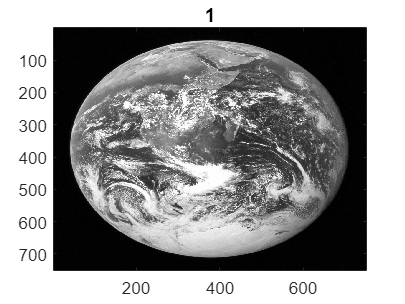

T1 = 751×750 uint8 matrix
   3   1   3   1   2   2   2   2   2   1   1   2   2   3   3   2   1   2   4   1   7   5   0   2   1   2   1   2   0   4   3   1   4   2   2   3   1   1   3   3   1   1   1   2   2   2   3   2   3   2
   5   2   2   3   1   2   1   3   3   4   2   2   0   2   1   1   2   0   3   1   3   1   5   1   0   1   1   1   1   1   1   0   0   2   2   1   2   1   1   1   3   2   1   1   3   3   1   2   1   0
   1   2   2   2   4   3   0   2   2   2   3   3   4   3   2   1   1   3   1   1   5   3   2   2   3   2   4   3   3   0   1   1   2   1   3   2   1   1   2   1   5   2   2   2   1   2   1   1   0   2
   3   3   3   3   0   3   2   1   2   2   1   4   3   2   2   1   1   0   0   2   1   3   2   0   2   2   5   4   5   3   4   2   3   2   3   1   1   0   1   2   0   1   0   1   1   2   1   4   2   1
   3   2   4   2   3   1   1   1   0   3   1   2   1   0   2   2   1   3   2   2   3   2   3   1   1   1   2   2   1   1   1   0   2   2   3   1   2   2   2   3   2   2  

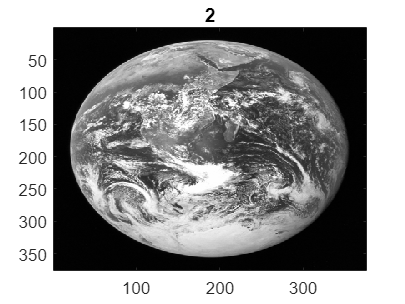

T1 = 751×750 uint8 matrix
   3   1   3   1   2   2   2   2   2   1   1   2   2   3   3   2   1   2   4   1   7   5   0   2   1   2   1   2   0   4   3   1   4   2   2   3   1   1   3   3   1   1   1   2   2   2   3   2   3   2
   5   2   2   3   1   2   1   3   3   4   2   2   0   2   1   1   2   0   3   1   3   1   5   1   0   1   1   1   1   1   1   0   0   2   2   1   2   1   1   1   3   2   1   1   3   3   1   2   1   0
   1   2   2   2   4   3   0   2   2   2   3   3   4   3   2   1   1   3   1   1   5   3   2   2   3   2   4   3   3   0   1   1   2   1   3   2   1   1   2   1   5   2   2   2   1   2   1   1   0   2
   3   3   3   3   0   3   2   1   2   2   1   4   3   2   2   1   1   0   0   2   1   3   2   0   2   2   5   4   5   3   4   2   3   2   3   1   1   0   1   2   0   1   0   1   1   2   1   4   2   1
   3   2   4   2   3   1   1   1   0   3   1   2   1   0   2   2   1   3   2   2   3   2   3   1   1   1   2   2   1   1   1   0   2   2   3   1   2   2   2   3   2   2  

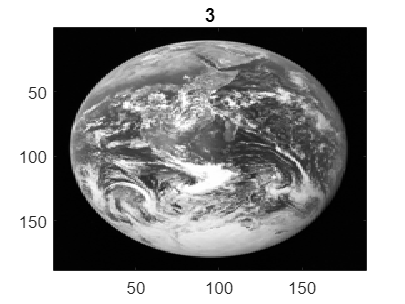

T1 = 751×750 uint8 matrix
   3   1   3   1   2   2   2   2   2   1   1   2   2   3   3   2   1   2   4   1   7   5   0   2   1   2   1   2   0   4   3   1   4   2   2   3   1   1   3   3   1   1   1   2   2   2   3   2   3   2
   5   2   2   3   1   2   1   3   3   4   2   2   0   2   1   1   2   0   3   1   3   1   5   1   0   1   1   1   1   1   1   0   0   2   2   1   2   1   1   1   3   2   1   1   3   3   1   2   1   0
   1   2   2   2   4   3   0   2   2   2   3   3   4   3   2   1   1   3   1   1   5   3   2   2   3   2   4   3   3   0   1   1   2   1   3   2   1   1   2   1   5   2   2   2   1   2   1   1   0   2
   3   3   3   3   0   3   2   1   2   2   1   4   3   2   2   1   1   0   0   2   1   3   2   0   2   2   5   4   5   3   4   2   3   2   3   1   1   0   1   2   0   1   0   1   1   2   1   4   2   1
   3   2   4   2   3   1   1   1   0   3   1   2   1   0   2   2   1   3   2   2   3   2   3   1   1   1   2   2   1   1   1   0   2   2   3   1   2   2   2   3   2   2  

figure();
for i = 1:4    
    T1 = im2gray(I1) %DiffGaus(I1,15,1,2*sqrt(2),0);
    im{i} = imresize(T1,k);
    a = cell2mat(im(i));
    show_image(a)
    title(i)
    k = k/2;
    I1 = T1;
end

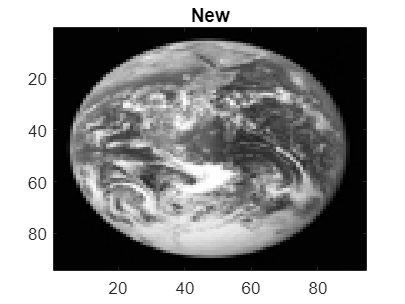


im2 = uint8.empty(0,5);

for i = 1:4
    I2 = cell2mat(im(i));
    t = DiffGaus(I2,15,1,2*sqrt(2),0);
    im2{i} = t;
    title('New')
    
end

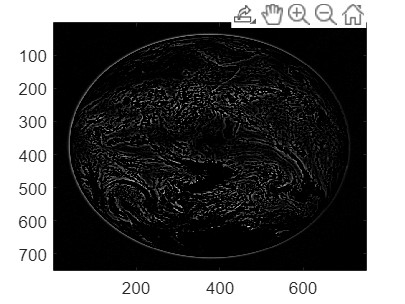

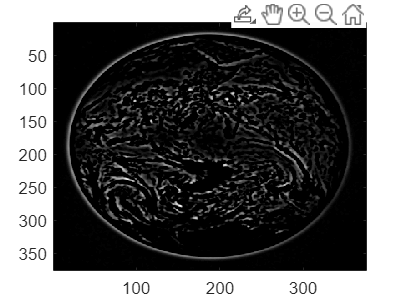

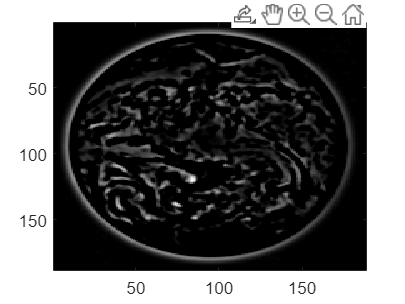

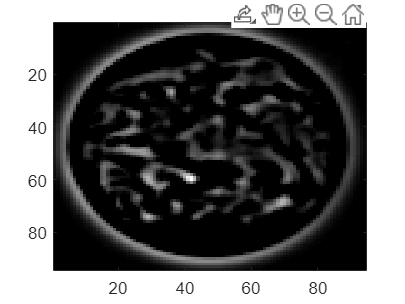

for i = 1:4
    a = cell2mat(im2(i));
    show_image(a);

end

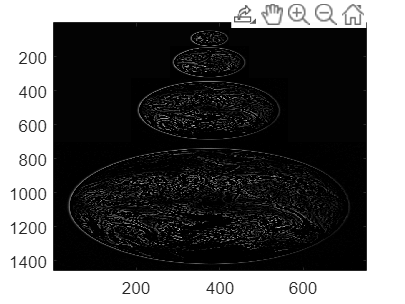

%
fig = ones(1456,751,3);
r = fig(:,:,1);
g = fig(:,:,2) ;
b = fig(:,:,3);
[x,y] = size(r);
for i = 1:4
    a = cell2mat(im2(i));
    ra = a; %im2bw(a,.01); %(:,:,1);
    %ga = a(:,:,2);
    %ba =a(:,:,3);
    [xa,ya] = size(ra);
    add = zeros(376,1);
    
    if (y-ya) ==  0
        r(x-xa:x,y-ya:y) = ra;
        %b(x-xa:x,y-ya:y) = ga;
        %b(x-xa:x,y-ya:y) = ba;

        x = x -xa;

    else
        y1 = floor((y-ya)/2);
        y2 = ceil((y-ya)/2);
        if y1 == 0
            y1 = 1;
            y2 = 0;
        else
            y1 = y2;
        end
        
        if ya == 375
            ra1 = [ra add];
         %   ga1 = [ga add];
          %  ba1 = [ba add];
        else
            ra1 = ra;
           % ga1 = ga;
            %ba1 = ba;
        end
        
        if x ==xa
            xa = 47;
            x = x+2;
            y= y -1;

        end
        r(x-xa:x-1,y1:y-y1) = ra1;
        %g(x-xa:x-1,y1:y-y1) = ga1;
        %b(x-xa:x-1,y1:y-y1) = ba1;

        x = x - xa;
        
       

    end
end
f = r; %cat(3,r,g,b);
show_image(f)

function y = DiffGaus(I,fsize,sig1,sig2,lap)
    n = fsize;
    f1 = zeros(fsize,fsize);
    for i = 1:fsize
        for j = 1:fsize
            f1(i,j) = 1/(2*pi*sig1*sig1) * exp(-((i-(n+1)/2)^2+(j-(n+1)/2)^2)/(2*sig1^2));
        end
    end
    f2 = zeros(fsize,fsize);
    for i = 1:fsize
        for j = 1:fsize
            f2(i,j) = 1/(2*pi*sig2*sig2) * exp(-((i-(n+1)/2)^2+(j-(n+1)/2)^2)/(2*sig2^2));
        end
    end
    
    y1 = imfilter(I,f1);
    y2 = imfilter(y1,f2);
    y2 = y2 - y1;

    y2 = uint8(y2);
    if lap==1
        y2 = I;
        y = locallapfilt(y2,2,.2);
    else
        y = im2gray(y2); 
    end

end

